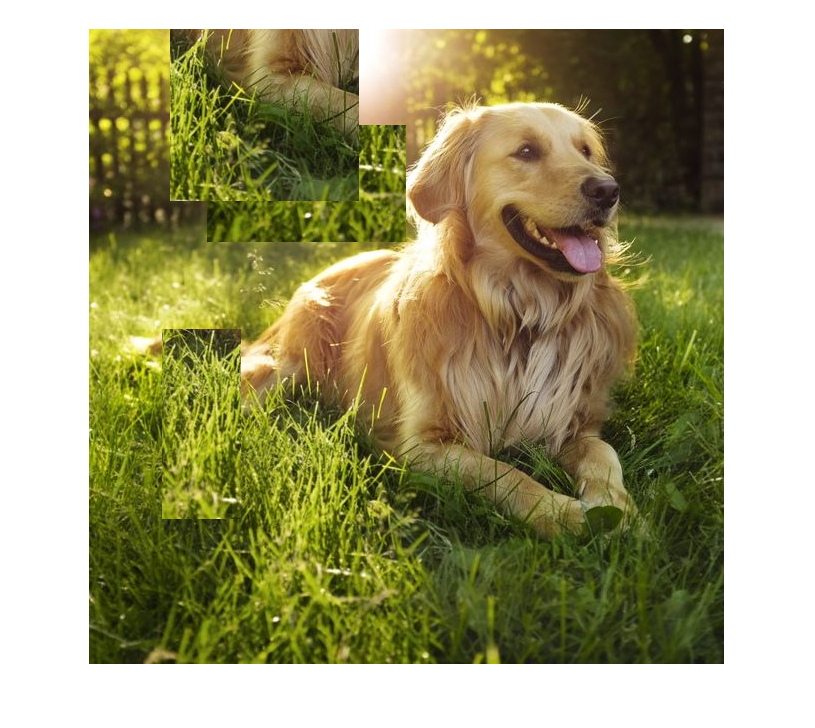

img = imread("squaredog.jpg");
%imshow(img);
R = img(:,:,1);
G = img(:,:,2);
B = img(:,:,3);

for i = 1: randi([3,5])
    squareSizeX = randi([50,200]);
    squareX = randi([0,635-squareSizeX]);
    rangeX1 = squareX:squareX+squareSizeX;
    
    squareSizeY = randi([50,200]);
    squareY = randi([0,635-squareSizeY]);
    rangeY1 = squareY:squareY+squareSizeY;
    
    
    squareX = randi([0,635-squareSizeX]);
    rangeX2 = squareX:squareX+squareSizeX;
    
    squareY = randi([0,635-squareSizeY]);
    rangeY2 = squareY:squareY+squareSizeY;


    R(rangeX1,rangeY1) = R(rangeX2,rangeY2);
    G(rangeX1,rangeY1) = G(rangeX2,rangeY2);
    B(rangeX1,rangeY1) = B(rangeX2,rangeY2);

end
%imshow(img)
imshow(cat(3,R,G,B));